%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Elaborated by Natanael Bolson
% Prof. Tad Patzek and Maxim Yutkin
% EGG-ANPERC-KAUST 12/2020
% Description: Compare Sustainability methods:
% Optimum (Correlation determines the place of the indicators)
% Proposed (Indicators placed based on analytical analysis )
% Permutation (All permutation of the indicators 2520)
% Histogram to analyze the difference and generate tables
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

clc
clear 
close all
t0=cputime;


## Load data

load ../Data/Data_Indicators.mat
load ../Data/Data_EIA_H.mat
% Vector that indicates the mirrors
load ../Data/Clean_Mirrors.mat

## Variables

% Select a specific year
year=2015;
index=year-1989;

% Labels
Labels=strtrim(Data_EIA_H.Labels);

CO2_N=Indicators.GHG_N(:,index);
Exp_N=Indicators.Exp_N(:,index);
GDP_N=Indicators.GDP_N(:,index);
HDI_N=Indicators.HDI_N(:,index);
Land_N=Indicators.Land_N(:,index);
Mat_N=Indicators.Mat_N(:,index);
Ren_N=Indicators.Ren_N(:,index);
Water_N=Indicators.Water_N(:,index);

% Correction in the Labels (abbreviating names)
Labels([8 159 204 208 219])={'Antigua','Palestine','Bahamas','Trinidad','UAE'};


% Indicators Proposed
  Indicators=[GDP_N,HDI_N,Exp_N,...
        Ren_N,Land_N,Water_N,Mat_N,...
        CO2_N,GDP_N];

% Indicators Optimum 
  Indicators_opt=[GDP_N,CO2_N,...
      Exp_N,Ren_N,Water_N,Land_N,...
      Mat_N,HDI_N,GDP_N];

% Index to eliminate if want to avoid NaN 
  Clean=[1,5,7,11,22,28,38,44,47,53,56,61,66,67,70,71,72,73,75,76,81,82,84,...
        86,87,88,89,92,95,97,112,113,124,131,135,138,139,143,146,147,...
        152,153,155,159,167,169,173,174,175,176,177,178,183,188,189,...
        192,200,205,207,212,213,214,215,216,227,228];
 
 Indicators(Clean,:)=[];
 Indicators_opt(Clean,:)=[];

 Tab_Indicators=table(Labels,GDP_N,HDI_N,Exp_N,...
        Ren_N,Land_N,Water_N,Mat_N,CO2_N,GDP_N);
 Tab_Indicators(Clean,:)=[]

Tab_Indicators = 165×10 table
        Labels          GDP_N      HDI_N      Exp_N        Ren_N        Land_N      Water_N      Mat_N      CO2_N      GDP_N_1 
    _______________    ________    _____    _________    __________    _________    ________    _______    ________    ________

    {'Afghanistan'}    0.062215     0.49      0.33428      0.075899      0.45128           1          1     0.53687    0.062215
    {'Albania'    }     0.37531    0.788      0.87955         0.469       0.4256           1    0.73674     0.49028     0.37531
    {'Algeria'    }     0.49001    0.751            1     0.0012862      0.37566      0.2723          1     0.32334  

Labels(Clean,:)=[];
% save Tab_Indicators.mat Tab_Indicators
 

## Proposed


X=[0,45,90,135,180,225,270,315,360]*pi/180;
for n=1:size(Indicators,1)
    [x,y] = pol2cart(X,Indicators(n,:));
    Area_Proposed(n)=polyarea(x,y);
end

## Optimum

X=[0,45,90,135,180,225,270,315,360]*pi/180;
for n=1:size(Indicators_opt,1)
    [x,y] = pol2cart(X,Indicators_opt(n,:));
    Area_opt(n)=polyarea(x,y);
end

## Permutation 2520

for n=1:size(Indicators,1)
    Y= Indicators(n,2:8);
    P=perms(Y);
    
    % Eliminate mirrors
    P(find(isnan(L)),:)=[]; 

    for m=1:size(P,1)
        [x,y]=pol2cart(X,[Indicators(n,1) P(m,:) Indicators(n,1)]);
        Area(m)=polyarea(x,y);
    end
    Mean_Area25(n)=nanmean(Area);
    Area(isnan(Area))=[];
    
end

% Make table
Tab=table(Labels,Area_Proposed',Area_opt',Mean_Area25',Area_Proposed'./Area_opt',Area_opt'./Mean_Area25',Area_Proposed'./Mean_Area25');
Tab.Properties.VariableNames={'Country','Proposed','Optimum','A2520','RatioOpt','RatioOptMean','RatioMean'}

Tab = 165×7 table
        Country        Proposed    Optimum     A2520     RatioOpt    RatioOptMean    RatioMean
    _______________    ________    _______    _______    ________    ____________    _________

    {'Afghanistan'}    0.80449     0.61418    0.64414     1.3099       0.95349         1.2489 
    {'Albania'    }     1.1697      1.1003     1.1593     1.0631       0.94916          1.009 
    {'Algeria'    }    0.69902     0.73552    0.73895    0.95038       0.99536        0.94597 
    {'Angola'     }    0.96075     0.75867    0.92108     1.2663       0.82368         1.0431 
    {'Antigua'    }    0.44885     0.46637    0.35272    0.96243        1.3222         1.2725 
    {'Argentina'  }     1.1528      1.0912      1.151     1.0564       0.94802

% save Tab_area_opt.mat Tab;

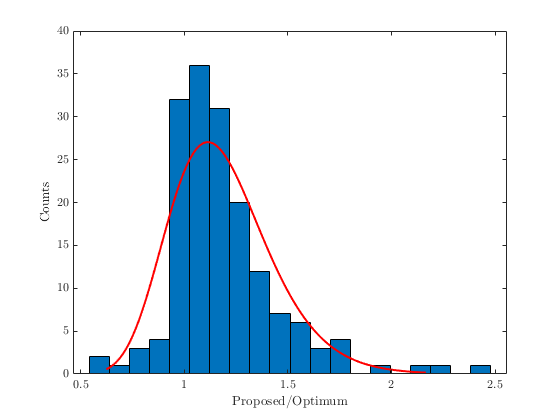

figure
histfit(Tab.RatioOpt,20,'lognormal')
xlabel('Proposed/Optimum',"Interpreter","latex")
ylabel('Counts',"Interpreter","latex")
set(gca,'Fontsize',12,'TickDir','in','FontWeight','normal','GridAlpha',0.13,...
    'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')

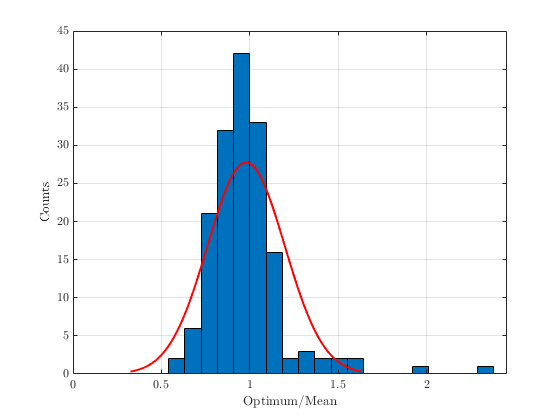

figure
histfit(Tab.RatioOptMean,20)
xlabel('Optimum/Mean',"Interpreter","latex")
ylabel('Counts',"Interpreter","latex")
box on 
grid on
set(gca,'Fontsize',12,'TickDir','in','FontWeight','normal','GridAlpha',0.13,...
    'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')

% print('-dpdf','-r400','Hist_ratio.pdf')

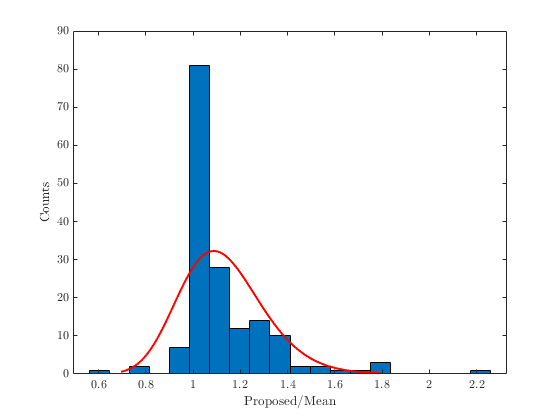

figure
histfit(Tab.RatioMean,20,'lognormal')
xlabel('Proposed/Mean',"Interpreter","latex")
ylabel('Counts',"Interpreter","latex")
set(gca,'Fontsize',12,'TickDir','in','FontWeight','normal','GridAlpha',0.13,...
    'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')

t=cputime-t0;